clear all;
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;
x0_1=1; x0_2=3; x0_3=5.5; x0_4=10;
acc=0.00001; y0_1=-2000; y0_2=-4000; 
len1=40*pi; len2=70*pi; len3=-30*pi; len4=-30*pi; len5=25*pi; len6=15*pi; len7=-1*pi; len8=-1*pi;

RelTol=acc ; AbsTol=acc ; InitialStep=acc ;
options=odeset('RelTol', RelTol ,'AbsTol', AbsTol, 'InitialStep', InitialStep, 'NormControl','on');

% [T, XY]= ode45(@odefcn, [0 10], [1 0], options);

clear all
load("workspace.mat")

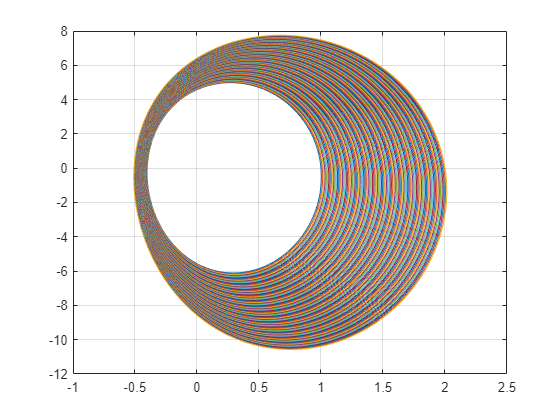

% Starting values of x
values=setdiff(1:0.01:2,0);

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [T(i),x,y] = ode45cycles(0,x(1),0,0.000000001,1);
    x2(i)=values(i);
    z = findZero(x,y);
    xdif(i)=z(end)-z(1);
    plot(x,y);
    hold on
end
grid on
hold off

% Starting values of x
values=setdiff(1:0.01:2,0);

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [T(i),x,y] = RK4cycles(0,x(1),0,1);
    x2(i)=values(i);
    z = findZero(x,y);
    xdif(i)=z(end)-z(1);
    plot(x,y);
    hold on
end
grid on
hold off

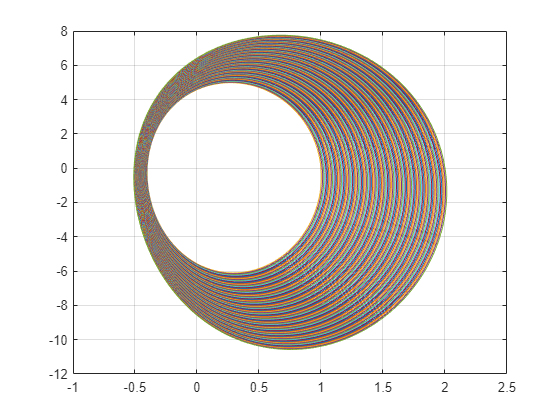

function dz=odefcn(t, z) %
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1) ,z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function [T,XY] = RK4(x,y,ti,tf,h)
    
    % Runge-Kutta 4

        for i=1:1:2

            k1=odefcn(i*h, [x(i), y(i)]);
        
            k2=odefcn(i*h+h/2, [x(i)+h/2*k1(1), y(i)+h/2*k1(2)]);
            
            k3=odefcn(i*h+h/2, [x(i)+h/2*k2(1), y(i)+h/2*k2(2)]);
            
            k4=odefcn(i*h+h, [x(i)+h*k3(1), y(i)+h*k3(2)]);
            
            x(i+1)=x(i) + h/6*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
            y(i+1)=y(i) + h/6*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
                    
        end

        i=3;
        T(1)=ti;T(2)=ti+h;

        while T(i-1)<tf

            k1=odefcn(i*h, [x(i), y(i)]);
                    
            k2=odefcn(i*h+h/2, [x(i)+h/2*k1(1), y(i)+h/2*k1(2)]);
            
            k3=odefcn(i*h+h/2, [x(i)+h/2*k2(1), y(i)+h/2*k2(2)]);
            
            k4=odefcn(i*h+h, [x(i)+h*k3(1), y(i)+h*k3(2)]);
            
            x(i+1)=x(i) + h/6*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
            y(i+1)=y(i) + h/6*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
            T(i)=T(i-1)+h;
            i=i+1;
        end
        XY=[x,y];
        T=T';
end

function [Te,x,y]=ode45cycles(ti,x0,y0,acc,n)
    options=odeset('RelTol', acc ,'AbsTol', acc, 'InitialStep', acc, 'NormControl','on');
    tf=ti+10;
    k=1+2*n;
    [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
    y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    count=0;cmax=2;

    while size(y_sign_change,1)<k && count<cmax
        count=count+1;
        [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
        tf=tf+100;
        y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    end

    if(count==cmax)
%         ci=y_sign_change(2)+1;
%         T=T(1:ci);
%         XY=XY(1:ci,:);
    else
        ci=y_sign_change(k)+1;
    
        T=T(1:ci);
        XY=XY(1:ci,:);
    end
    x=XY(:,1);
    y=XY(:,2);
    Te = T(end);
end

function [Te,x,y]=RK4cycles(ti,x0,y0,n)
    tf=ti+10;
    k=1+2*n;
    h=0.001;
    vecSize=ceil(abs(tf-ti)/n);
    XY=zeros(vecSize,2);
    T=zeros(vecSize,1);
    XY(1,1)=x0;XY(1,2)=y0;

    [T, XY]= RK4(XY(:,1),XY(:,2),ti,tf,h);
    y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    count=0;cmax=2;

    while size(y_sign_change,1)<k && count<cmax
        count=count+1;
        [T, XY]= RK4(XY(:,1),XY(:,2),ti,tf,h);
        tf=tf+100;
        y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    end

    if(count==cmax)
%         ci=y_sign_change(2)+1;
%         T=T(1:ci);
%         XY=XY(1:ci,:);
    else
        ci=y_sign_change(k)+1;
    
        T=T(1:ci);
        XY=XY(1:ci,:);
    end
    x=XY(:,1);
    y=XY(:,2);
    Te = T(end);
end


function x0 = findZero(x,y)

    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                    % Returns Approximate Zero-Crossing Indices Of Argument Vector
    dy = zci(y);                                                            % Indices of Approximate Zero-Crossings
    for k1 = 1:size(dy,1)-1
        b = [[1;1] [x(dy(k1)); x(dy(k1)+1)]]\[y(dy(k1)); y(dy(k1)+1)];      % Linear Fit Near Zero-Crossings
        x0(k1) = -b(1)/b(2);                                                % Interpolate ‘Exact’ Zero Crossing
        mb(:,k1) = b;                                                       % Store Parameter Estimates (Optional)
    end
end